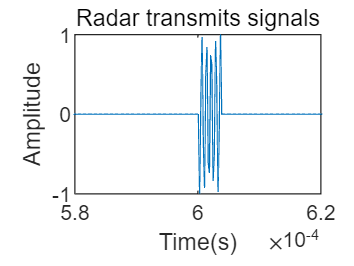

% 脉冲波雷达非相参积累检测和CFAR检测仿真
clc; clear; close all;

%% 参数设定
clock = 5 * 10 ^ 6;  % FPGA的时钟频率5MHz
clk = 1 / clock;     % FPGA的时钟周期
PRI = 2 * 10 ^ (-3); % 雷达的PRI，2ms
tao = 4 * 10 ^ (-6); % 雷达的脉冲宽度，4us
N = 1;               % 脉冲个数
fs = 1 / clk;        % 采样频率，5MHz
t1 = 6 * 10 ^ (-4);  % 回波延迟，0.6ms
A = 1;               % 脉冲幅度
P = 10;              % 非相参积累次数
noise_amplitude = 1; % 噪声幅度
t2 = 128 * clk;      % 雷达保护单元
NZ = ceil(tao * fs); % 卷积窗口的长度


%% 生成雷达发射信号
% 定义时间轴
t = linspace(0, N * PRI, N * fs * PRI);
% 构建一个脉冲回波信号
pulse = zeros(1, fs * PRI);
timee = (ceil(t1 * fs)):(ceil((t1 + tao) * fs));  % 延迟后的脉冲信号
pulse(timee) = sin(linspace(-pi * 5, pi * 5, length(pulse((ceil(t1 * fs)):(ceil((t1 + tao) * fs))))));
% 绘图
figure;
plot(t(1:PRI * fs), pulse);
xlabel('Time(s)');
xlim([0.58 * 10 ^ (-3) 0.62 * 10 ^ (-3)]);
ylabel('Amplitude');
ylim([-1 1]);
title("Radar transmits signals")

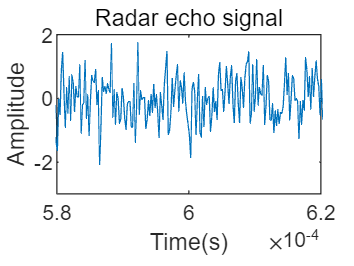


%% 生成多组回波信号
Initial_pulse = repmat(pulse, P, N); % 进行重组
Noise_pulse = Initial_pulse + sqrt(0.5) * randn(size(Initial_pulse));

% 绘制产生的第一个回波信号
figure
plot(t, Noise_pulse(1, :));
xlabel('Time(s)');
xlim([0.58 * 10 ^ (-3) 0.62 * 10 ^ (-3)]);
ylabel('Amplitude');
title("Radar echo signal")

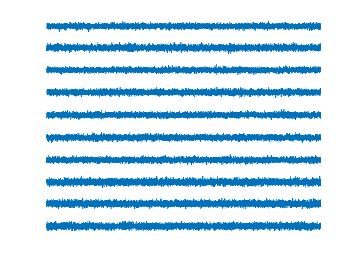


% 绘制产生的所有回波信号
figure
title('Full echo signals');
for c = 1:P
    subplot(P, 1, c);
    plot(t, Noise_pulse(c, :));
    xlim([0 max(t)]);
    axis off
end

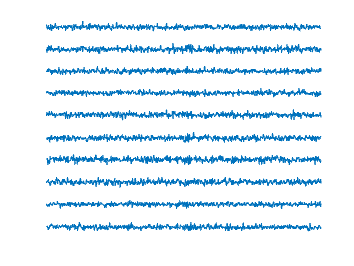


%% 截取回波信号
% 设置波门
gate_length = 0.12 * 10 ^ (-3);              % 波门长度为2倍脉冲宽度
gate_samples = round(gate_length * fs);      % 波门长度对应的采样点数
gate_start = round((0.54 * 10 ^ (-3)) * fs); % 波门的起始采样点
gate_end = gate_start + gate_samples - 1;    % 波门的结束采样点

echo_signals = Noise_pulse(:, gate_start:gate_end); % 截取回波信号

% 绘制截取后的全部回波信号
figure
title('Echo signal with wavegate');

t_gate = linspace(0, gate_length, gate_samples); % 波门对应的时间轴
for c = 1:P
    subplot(P, 1, c);
    plot(t_gate, echo_signals(c, :));
    xlim([0 max(t_gate)]);
    axis off
end

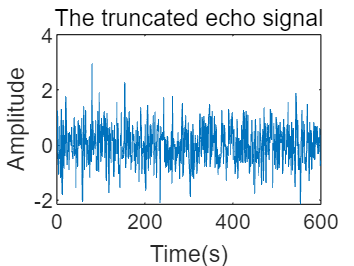


% 绘制截取后的第一个回波信号
figure
plot(echo_signals(1, :));
xlabel('Time(s)')
ylabel('Amplitude')
title('The truncated echo signal')

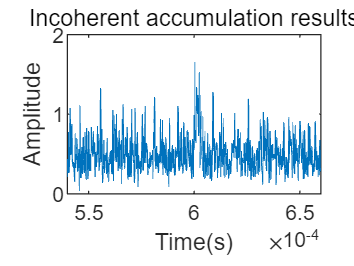


%% 非相参积累得到非相参后的信号
Nonnoncoherent_pulse = sum(echo_signals .^ 2, 1) / P; % 重构非相参积累公式,得到非相参信号

% 绘制非相参积累后的信号
figure
plot(t(2700:2700 + 599), Nonnoncoherent_pulse)
xlabel('Time(s)');
xlim([0.54 * 10 ^ (-3) 0.66 * 10 ^ (-3)]);
ylabel('Amplitude');
title("Incoherent accumulation results")

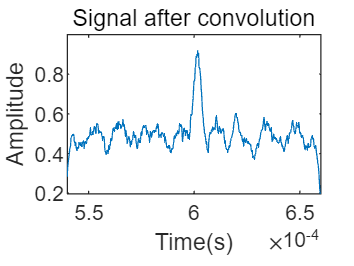


%% 循环卷积平滑信号
% 构造矩形窗口作为卷积核
h = ones(NZ, 1);

% 进行卷积运算并提取结果
y = conv(Nonnoncoherent_pulse, h, 'same') / NZ;

% 绘制卷积后的信号
figure();
plot(t(2700:2700 + 599), y);
xlabel('Time(s)');
xlim([0.54 * 10 ^ (-3) 0.66 * 10 ^ (-3)]);
ylabel('Amplitude');
title("Signal after convolution")

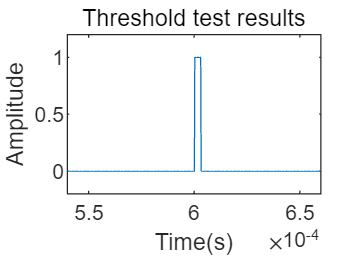


%% CFAR检测
% 计算门限
% 获取左右窗口的噪声平均值
a1 = sum(Nonnoncoherent_pulse(1:ceil(t2 * fs))) / length(Nonnoncoherent_pulse(1:ceil(t2 * fs))); %左边窗口的阈值
a2 = sum(Nonnoncoherent_pulse((gate_samples - ceil(t2 * fs)):gate_samples)) / length(Nonnoncoherent_pulse((gate_samples - ceil(t2 * fs)):gate_samples)); %右边窗口的阈值

% 取左右窗口的平均值的1.6倍作为阈值
threshold = 1.6 * ((a1 + a2) / 2);

% 检测目标
idx = find(y > threshold);

% 绘制检测结果
view = zeros(1, gate_samples);
view(idx) = 1;
figure;
plot(t(2700:2700 + 599), view(1:gate_samples));
xlabel('Time(s)');
xlim([0.54 * 10 ^ (-3) 0.66 * 10 ^ (-3)]);
ylabel('Amplitude');
title("Threshold test results")
ylim([-0.2 1.2]);